%convolution linear
x=input('Enter x[n]:')

x =      9     8     6     4


h=input('Enter h[n]:')

h =      2     7     9     1


m=length(x);
n=length(h);
X=[x,zeros(1,n)];
H=[h,zeros(1,m)];
for i=1:n+m-1
Y(i)=0;
for j=1:m
if(i-j+1>0)
Y(i)=Y(i)+X(j)*H(i-j+1);
end
end
end
Y

Y = 1×21 logical array
   1   1   1   1   1   1   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0


subplot(2,2,1)
stem(x);
title('Input x[n]');
subplot(2,2,2);
stem(h);
title('Input h[n]')
subplot(2,2,3);
stem(Y);
title('Linear convolution output y[n]')


%covolution circular
x=input('Enter x[n]:');
h=input('Enter h[n]:');
rev_h = [h(1) h(1,numel(x):-1:2)];
y=zeros(1,numel(x));
z=zeros(1,numel(x));
for i=1:numel(x)
z=x.*rev_h;
y(i)=sum(z);
temp = rev_h(1,numel(z));
rev_h = [temp rev_h(1,1:numel(y)-1)];
end
disp(y);

    99    46    86   130



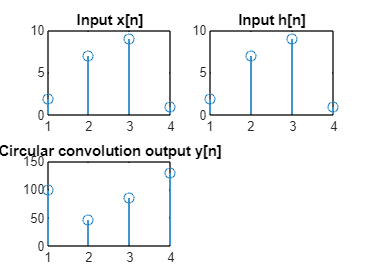

subplot(2,2,1)
stem(x);
title('Input x[n]');
subplot(2,2,2)
stem(h);
title('Input h[n]');
subplot(2,2,3);
stem(y);
title('Circular convolution output y[n]')